# Power Amplifier Characterization

This example shows how to characterize a power amplifier (PA) using measured input and output signals of an NXP Airfast PA. Optionally, you can use a hardware test setup including an NI PXI chassis with a vector signal transceiver (VST) to measure the signals at run time. 

You can use the characterization results to simulate the PA using the [comm.MemorylessNonlinearity](docid:comm_ref#bsnfpwe_2) System object or [Memoryless Nonlinearity](docid:comm_ref#fp687424) block. For a PA model with memory, you can use [Power Amplifier](docid:simrf_ref#mw_78f70ded-c2df-4f94-83b6-24549c864f01) block. You can use these models to design digital predistortion (DPD) using  [comm.DPD](about:blank<comm.DPDdocid:comm_ref#mw_cbe2894c-e909-4577-af55-33665d850fcf>) and [comm.DPDCoefficientEstimator](about:blank<comm.DPDCoefficientEstimatordocid:comm_ref#mw_78ed136d-2255-4050-b9b0-ea1d551eb7eb>) System objects or [DPD](docid:comm_ref#mw_be56ad90-54c2-4d23-85b6-ace4372a97a0) and [DPD Coefficient Estimator](docid:comm_ref#mw_aedcc813-5d06-4251-b4fe-d0592034887f) blocks. For more information, see [Digital Predistortion to Compensate for Power Amplifier Nonlinearities](docid:comm_ug#example_comm_simrf_PACharacterizationWithDPDForReducedDistortionExample). 

## Optional Hardware and Software

This example can run on an NI PXI chassis with a VST to measure PA input and output signals during run time. The VST is a high-bandwidth RF instrument that combines a Vector Signal Generator (VSG) with a Vector Signal Analyzer (VSA). The following NI PXI chassis configuration was used to capture the saved signal:

- NI PXIe-5840 Vector Signal Transceiver (VST)

- NI PXIe-4139 Source Measure Unit (SMU)

- NI PXIe-4145 SMU

- [NI RFmx SpecAn](https://www.ni.com/en-us/support/downloads/software-products/download.rfmx-specan.html#341840) software

- [NI-RFSG](https://www.ni.com/en-us/support/downloads/drivers/download.ni-rfsg.html#344209) software

- [NI-RFSG Playback Library](https://www.ni.com/en-us/support/downloads/drivers/download.ni-rfsg-playback-library.html#332845) software

As the device under test (DUT), this example uses an NXP Airfast LDMOS Doherty PA with operating frequency 3.6-3.8 GHz and 29 dB gain. This PA requires 29V, 5V, 3 V, 1.6V and 1.4V DC bias, which are provided using PXIe-4139 and PXIe-4145 SMUs.

Install MATLAB® on the NI PXI controller to run this example with the hardware setup, which is illustrated in the following figure. MATLAB, running on the PXI controller, generates test waveform and downloads the waveform to the VSG. The VSG transmits this test waveform to the PA and the VSA receives the impaired waveform at the PA output. MATLAB collects the PA output from the VSA and performs PA characterization.

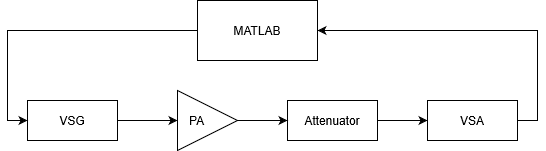

Set dataSource variable to `"Hardware"` to run a test signal though the PA  using the hardware setup described above. The test signal can be either a 5G-like OFDM waveform or two tones, as described in the following section. Set dataSource variable to `"From file"` to use prerecorded data. 

dataSource = "From file";

## Generate Test Signals

If t`estSignal` is `"OFDM"`, this example uses a 5G-like OFDM waveform with 64-QAM modulated signals for each subcarrier. If t`estSignal` is `"Tones"`, this example uses two tones at 1.8 MHz and 2.6 MHz, to test the intermodulation caused by the PA.

testSignal = "Tones";
switch testSignal
  case "OFDM"
    bw = 15e6;
    [txWaveform,sampleRate,numFrames] = helperPACharGenerateOFDM(bw);
  case "Tones"
    bw = 3e6;
    [txWaveform,sampleRate,numFrames] = helperPACharGenerateTones();
end

To identify high order nonlinearities, the test signal must be oversampled at least by the amount of expected order of nonlinearity. In this example, we run a grid search up to nonlinearity order of seven. Upsample by seven to cover possible seventh order nonlinearities. Also, normalize the waveform amplitude.

overSamplingRate = 7;
filterLength = 6*70;
lowpassfilter = firpm(filterLength, [0 8/70 10/70 1], [1 1 0 0]);
firInterp = dsp.FIRInterpolator(overSamplingRate, lowpassfilter);
txWaveform = firInterp([txWaveform; zeros(filterLength/overSamplingRate/2,1)]);
txWaveform = txWaveform((filterLength/2)+1:end,1);      % Remove transients
txWaveform = txWaveform/max(abs(txWaveform));   % Normalize the waveform
sampleRate = sampleRate * overSamplingRate;

## Hardware Test

If dataSource variable is set to `"From file"`, load the prerecorded data. `If dataSource` variable is set to `"Hardware", r`un the test signal through the PA using the VST. Create a helperVSTDriver object to communicate with the VST device. Set the resource name to the resource name assigned to the VST device. This example uses `'VST_01'`. For NI devices, you can find the resource name using the NI Measurement & Automation Explorer (MAX) application. 


  % Load the prerecorded results from VST
  switch testSignal
    case "OFDM"
      dataFileName = sprintf("helperPACharSavedData%dMHz",bw/1e6);
    case "Tones"
      dataFileName = "helperPACharSavedDataTones";
  end
  load(dataFileName,"results","sampleRate","overSamplingRate","testSignal","numFrames")


Map results into local variables.

referencePower = results.ReferencePower;
measuredAMToAM = results.MeasuredAMToAM;
paInput = results.InputWaveform;
paOutput = results.OutputWaveform;
linearGaindB = results.LinearGain;

Plot the spectrum of the test signal using [dsp.SpectrumAnalyzer](docid:dsp_ref#bthj29x-1) System object.

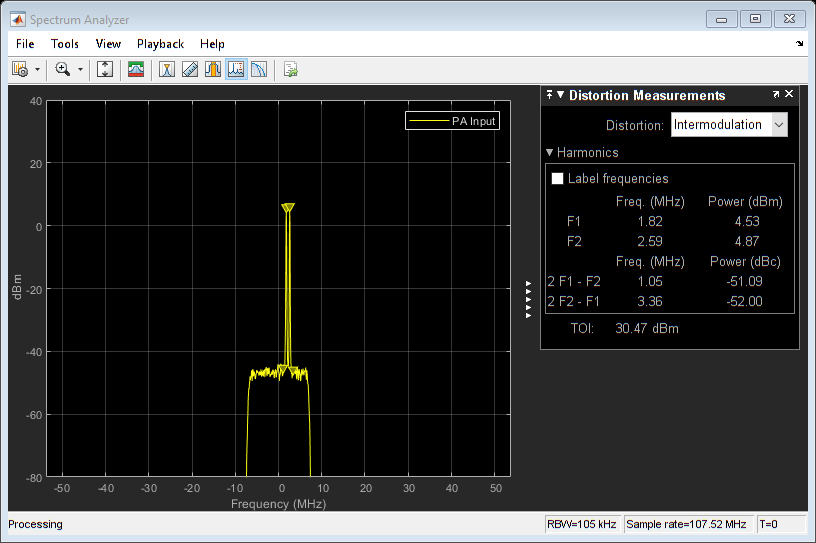

saInput = helperPACharPlotInput(paInput, sampleRate, testSignal, bw);

Plot the AM/AM characteristics of the PA.

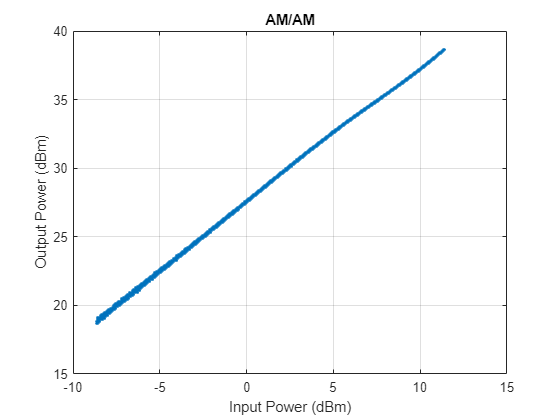

helperPACharPlotSpecAnAMAM(referencePower, measuredAMToAM)

For a better view, focus on gain vs input power instead of output power vs input power and plot again.

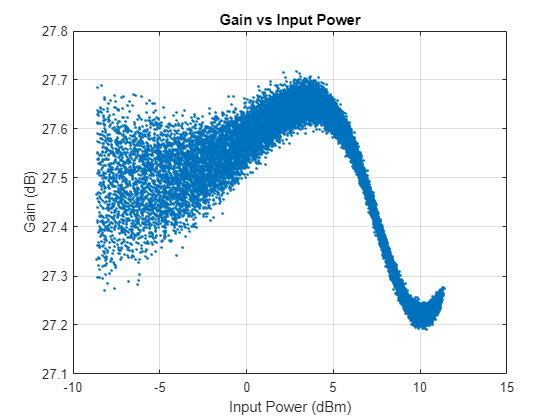

helperPACharPlotSpecAnGain(referencePower, measuredAMToAM)

The PA is mostly linear of the input power range -1 to 17 dBm, with only about 1dB variation over that range. The width of the gain curve is due to the memory effects of the PA. 

## PA Characterization

Use the measured PA input and output data to model the PA. Then, you can use this model to simulate a system that contains this PA and fine tune the parameters. This example considers three models: memoryless nonlinearity, memory polynomial and memory polynomial with cross terms. 

### Memoryless Nonlinearity Model

Memoryless nonlinear impairments distort the input signal amplitude and phase. The amplitude distortion is amplitude-to-amplitude modulation (AM/AM) and the phase distortion is amplitude-to-phase modulation (AM/PM). The [comm.MemorylessNonlinearity](docid:comm_ref#bsnfpwe_2) System object and [Memoryless Nonlinearity](docid:comm_ref#fp687424) block implements several such distortions. Use the PA input and output data to create a lookup table to use with this object or block.

To characterize the AM/AM transfer function, calculate the average output power for a range of input power values. Measurements are in volts over an overall 100 ohm impedance, split between the transmitter and receiver. Convert the measured baseband samples to power values in dBm. The +30 dB term is for dBW to dBm conversion and the -20 dB term is for the 100 ohm impedance.

paInputdBm  = mag2db(abs(paInput)) + 30 - 20;
paOutputdBm  = mag2db(abs(paOutput)) + 30 - 20;

Partition the input power values into bins. The `edges` variable contains the bin edges, and the `idx` variable contains the index of the bin values for each input power value. 

[N,edges,idx] = histcounts(paInputdBm, 'BinWidth', 0.5);

For each bin, calculate the midpoint of the bin, average output power and average phase shift. Do not include any input power value that is less than 20 dB below the maximum input power. Store the results in a three-column matrix where the first column is the input power in dBm, second column is the output power in dBm and last column is the phase shift. 

minInPowerdBm = max(paInputdBm) - 20;
minIdx = find(edges < minInPowerdBm, 1, 'last');
tableLen = length(edges)-minIdx-1;
inOutTable = zeros(tableLen,2);
for p = minIdx+1:length(edges)-1
  inOutTable(p-minIdx,1) = mean(paInputdBm(idx == p));   % Average input power for current bin
  inOutTable(p-minIdx,2) = mean(paOutputdBm(idx == p));  % Average output power for current bin
  inOutTable(p-minIdx,3) = mean(angle(paOutput(idx == p)./paInput(idx == p)));  % Average phase shift for current bin
end

Use the table in the comm.MemorylessNonlinearity System object to model the PA. Compare the estimated output with the actual output.

pa = comm.MemorylessNonlinearity('Method','Lookup table','Table',inOutTable,'ReferenceImpedance',100)

pa =   comm.MemorylessNonlinearity with properties:

                Method: 'Lookup table'
                 Table: [40×3 double]
    ReferenceImpedance: 100


paOutputFitMemless = pa(paInput);
err = abs(paOutput - paOutputFitMemless)./abs(paOutput);
rmsErrorMemless = rms(err)*100;
disp(['Percent RMS error in time domain is ' num2str(rmsErrorMemless) '%'])

Percent RMS error in time domain is 9.9173%


To visualize both the measured output signal and the fitted output signal, plot the actual and fitted time-domain output voltages.

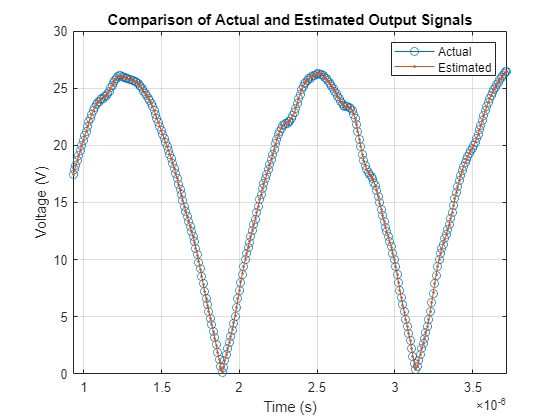

helperPACharPlotTime(paOutput, paOutputFitMemless, sampleRate)

Plot the magnitude of the gain.

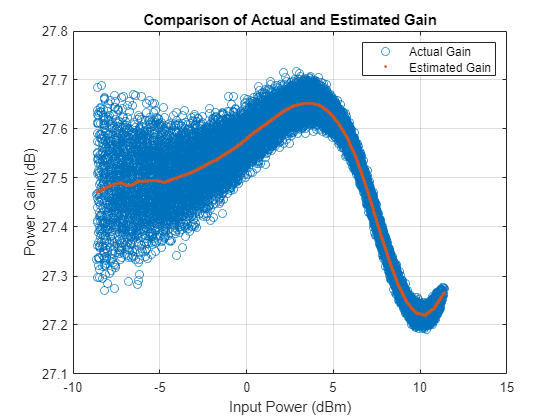

helperPACharPlotGain(paInput, paOutput, paOutputFitMemless)

### Memory Polynomial Model

The memory polynomial model includes the memory effects of the PA in addition to the nonlinear gain. Use the multipurpose helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) to determine the complex coefficients of a memory polynomial model for the amplifier characteristics. Set the model type to `'Memory Polynomial'`. 

modType = 'ctMemPoly';

Perform a grid search as shown in Appendix Grid Search for Memory Length and Polynomial Order. Based on this grid search results, the best fit is obtained when memory length and polynomial degree values are as follows:

memLen = 5;
degLen = 5;

Perform the fit and RMS error calculation for these values. Only half of the data is used to compute the fitting coefficients, as the whole data set will be used to compute the relative error. The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) calculates the coefficients of the model. 

numDataPts = length(paInput);
halfDataPts = round(numDataPts/2);

The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) is editable for custom modifications, and to return the desired matrix. The PA model has some zero valued coefficients, which results in a rank deficient matrix.

fitCoefMatMem = helperPACharMemPolyModel('coefficientFinder',             ...
  paInput(1:halfDataPts),paOutput(1:halfDataPts),memLen,degLen,modType);

disp(abs(fitCoefMatMem))

  Columns 1 through 6

   21.6931   42.3618         0         0         0    8.7876
         0         0         0         0         0         0
    4.1050         0         0         0         0         0
         0         0         0         0         0         0
    3.5180   22.4444         0         0         0   25.4118

  Columns 7 through 12

   67.8080         0         0         0    8.9481         0
         0         0         0         0         0         0
         0         0   15.3041         0         0         0
         0         0         0         0         0         0
   34.2904         0         0         0   30.4118   19.2974

  Columns 13 through 18

   22.8097         0         0    7.6535   14.2240         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0   14.8147         0         0   21.2473

  Columns 

To validate the fitting, use the helper function to compute percent RMS error with respect to the measured signal.

rmsErrorTimeMem = helperPACharMemPolyModel('errorMeasure', ...
  paInput, paOutput, fitCoefMatMem, modType);
disp(['Percent RMS error in time domain is ' num2str(rmsErrorTimeMem) '%'])

Percent RMS error in time domain is 4.7074%


To visualize both the measured output signal and the fitted output signal, plot the actual and fitted time-domain output voltages.

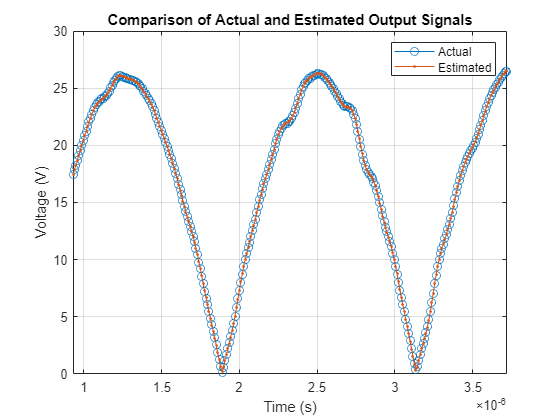

paOutputFitMem = helperPACharMemPolyModel('signalGenerator', ...
  paInput, fitCoefMatMem, modType);
helperPACharPlotTime(paOutput, paOutputFitMem, sampleRate)

Plot the magnitude of the gain.

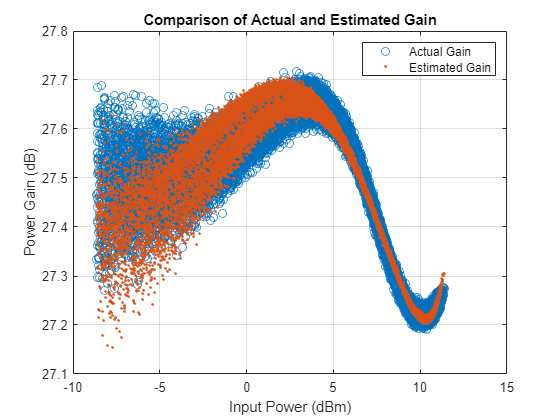

helperPACharPlotGain(paInput, paOutput, paOutputFitMem)

## Discussions

The percent RMS estimation error in time domain for the memoryless nonlinearity model, which is between 9% and 13%, is about 3 to 4 times more than the error for the memory polynomial model is, which is between 2% and 6%, for the OFDM signals with different bandwidths. 

Check the estimation error in frequency domain by plotting the spectrum of the actual PA output together with the spectrum of the estimated PA output for all three models. The memoryless nonlinearity table lookup model is not able to simulate the spectral growth seen in the measured PA output. For this PA, memory polynomial model provides a good approximation of the PA characteristics.

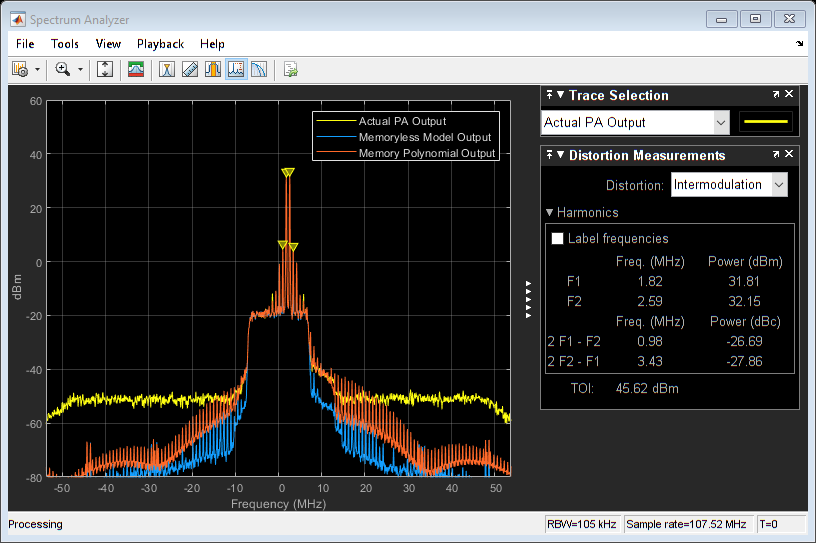

sa = helperPACharPlotSpectrum(...
  [paOutput paOutputFitMemless paOutputFitMem],...
  {'Actual PA Output','Memoryless Model Output', ...
  'Memory Polynomial Output'},...
  sampleRate,testSignal);

The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) can also use the memory polynomial with cross terms model, which includes the leading and lagging memory cross terms in addition to the memory effects of the PA and the nonlinear gain. Set the model type to `'Cross-Term Memory'` to explore this model.

For further exploration, try different memory length and polynomial degree combinations. Modify the oversampling factor and explore its effect on the PA model performance. Modify the helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) to try different PA models.

## Using PA Model for DPD Testing

Save the coefficient matrix of the PA model to be used in the [Power Amplifier block](docid:simrf_ref#mw_78f70ded-c2df-4f94-83b6-24549c864f01) for simulation at the system-level in the [DPD Testing with Simulated Power Amplifier Example](docid:comm_ug#example_comm_simrf_PACharacterizationWithDPDForReducedDistortionExample).

frameSize = floor(length(paInput)/numFrames);
paIn.signals.values = double(reshape(paInput(1:frameSize*numFrames,1),numFrames,frameSize));
paIn.signals.dimensions = frameSize;
paIn.time = [];
save('PAcoefficientsAndInput.mat','modType','fitCoefMatMem','memLen','degLen','paIn','linearGaindB')

## Appendix: Grid Search for Memory Length and Polynomial Order

Uncomment following lines to perform the grid search when the cost function is the percent RMS error in time. First choose the model type.

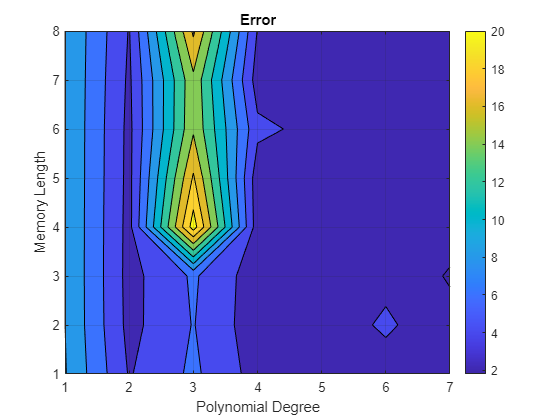

rmsErrorTime =    10.1322    3.8419    6.3995    3.1896    3.0458    3.0992    3.1089
   10.0108    3.3983    6.0940    2.8126    2.8370    4.3089    2.6585
   10.0073    3.3202    6.2931    2.8731    2.7558    3.4894    1.8057
   10.0088    3.3489   20.9612    2.8525    2.7465    2.5421    2.8452
   10.0091    3.4219   18.2575    2.8148    3.2546    3.7568    2.7897
   10.0118    3.4679   15.7120    4.4790    3.2911    2.7099    3.5456
   10.0130    3.6429   15.5288    3.0372    2.7211    3.6287    2.8695
   10.0122    3.8806   18.3543    3.8838    2.7005    3.4927    2.7076


modType = 'ctMemPoly';
rmsErrorTime = helperPACharGridSearchTime(paInput,paOutput,modType,overSamplingRate)

Repeat the search when the cost function is the percent RMS error in frequency.

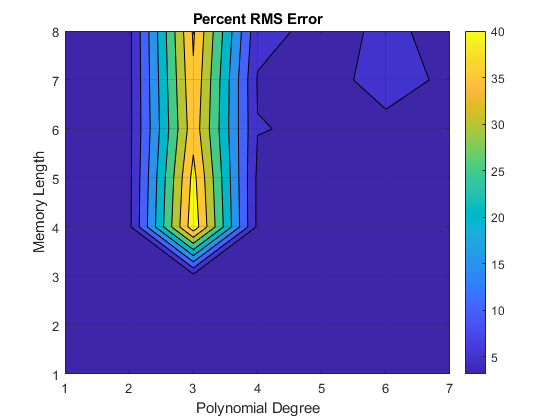

rmsErrorFreq =     4.0313    3.6966    3.4398    4.3072    4.0316    4.0488    4.0180
    4.0323    3.6819    3.4412    4.2413    4.2362    4.0264    4.0172
    4.0307    3.7169    3.4565    4.1571    3.9282    3.8367    3.1682
    4.0306    3.7805   43.3330    4.0200    3.8334    3.5958    3.6306
    4.0306    3.6708   41.6088    4.0663    3.8216    4.1173    3.6548
    4.0289    3.6817   38.2243    5.1446    4.5091    4.3698    4.2022
    4.0290    3.6654   39.3849    4.6982    4.0674    5.9400    4.5473
    4.0291    3.6313   40.6343    6.3978    3.7409    5.6589    3.9638


rmsErrorFreq = helperPACharGridSearchFrequency(paInput,paOutput,modType,overSamplingRate)

*Copyright 2020 The MathWorks, Inc.*